# Project with UQLab

## 1. Initiate UQLab

uqlab;

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\Users\upar\Desktop\ArijitFiles\PhD\PhDCourses\UQ\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



## 2. Defining the model: Capacitance measurement setup

ModelOptions.mFile = 'model_evaluation_1'; % use the provided model_evaluation_1.m file
myModel = uq_createModel(ModelOptions);     % Create the model object

Then the evaluation of model is as follows:

x0 = [100, 30, 1000]; %Input parameters (E, Vr, R)
y0 = uq_evalModel(myModel, x0) %Calculate capacitance in Farads

y0 = 1.0010e-06

## 3. Defining the probabilistic input model

The inputs for the function are three independent, Gaussian random variables:

% Voltage across the voltage source in V
InputOptions.Marginals(1).Name = 'E';
InputOptions.Marginals(1).Type = 'Gaussian';
InputOptions.Marginals(1).Moments = [100 0.45];

% Voltage across the shunt resistor in V
InputOptions.Marginals(2).Name = 'Vr';
InputOptions.Marginals(2).Type = 'Gaussian';
InputOptions.Marginals(2).Moments = [30 0.12];

% Shunt resistance in ohm
InputOptions.Marginals(3).Name = 'R';
InputOptions.Marginals(3).Type = 'Gaussian';
InputOptions.Marginals(3).Moments = [1000 1.5];

myInput = uq_createInput(InputOptions);    % Create the input object

## **(Extra: Visualising the sample space) **

## **3.1 Choosing a sampling strategy for the input variables according to their distributions and drawing samples:**

To draw samples from input object, we use the LHS method:

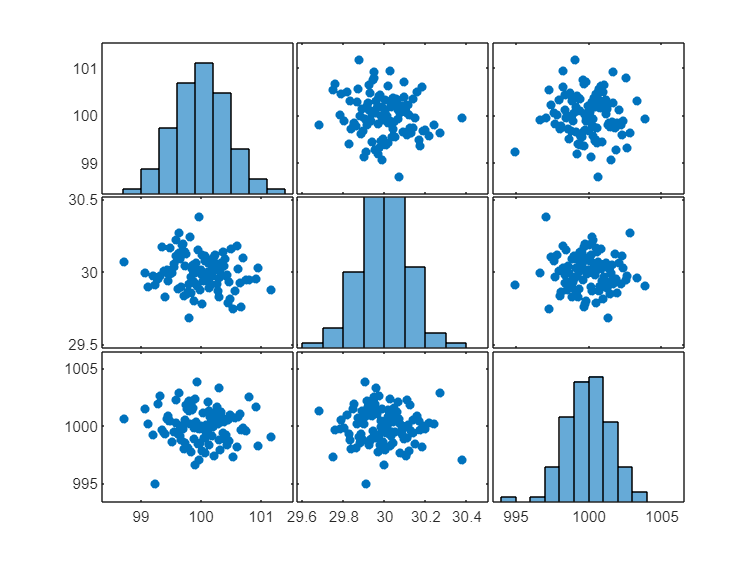

X = uq_getSample(myInput, 100, 'LHS');
plotmatrix(X)

## 3.2. Performing Monte Carlo simulation on the experimental design

% X was defined in the section 3.1
Y = uq_evalModel(myModel, X);

## 3.3 Plot histogram of Monte Carlo runs

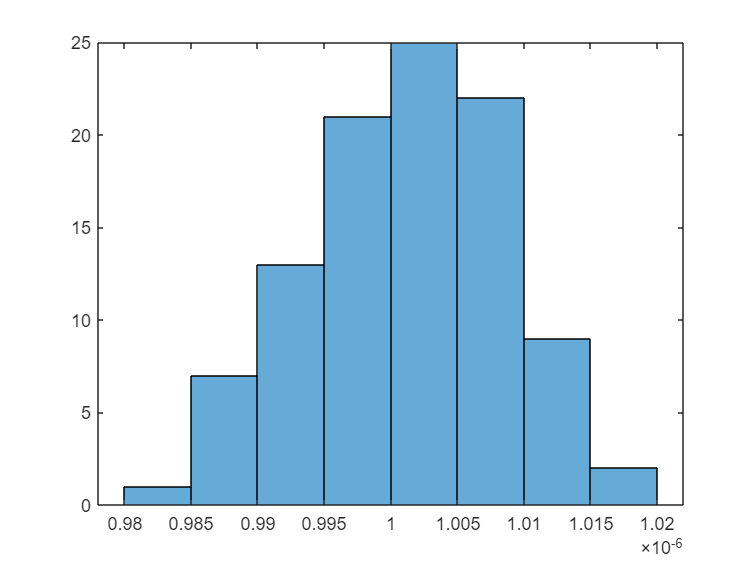

histogram(Y)

## 4. (Small Trial) Creating a PCE of degree 3 with 100 samples

## 4.1 Create a regression-based PCE using OLS for coefficient computation

clear MetaOptions
MetaOptions.Type = 'Metamodel';
MetaOptions.MetaType = 'PCE';
MetaOptions.Method = 'OLS';

MetaOptions.FullModel = myModel;
MetaOptions.Input = myInput;

MetaOptions.Degree = 3;

MetaOptions.ExpDesign.NSamples = 100; % N needs to be larger than P for OLS to work

myOLSPCE = uq_createModel(MetaOptions);

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: 5.734820e-13
---                 Calculation finished!                               ---


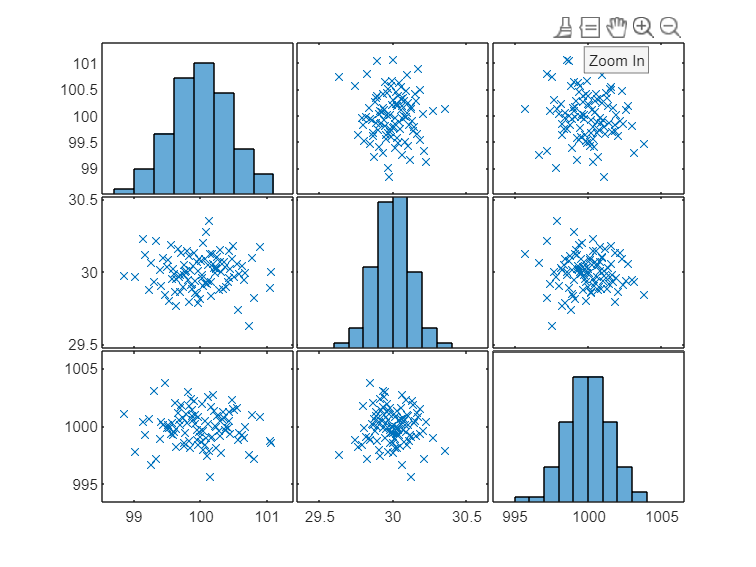

figure
plotmatrix(myOLSPCE.ExpDesign.X, 'x')

### Displaying the magnitude of PCE coefficients:

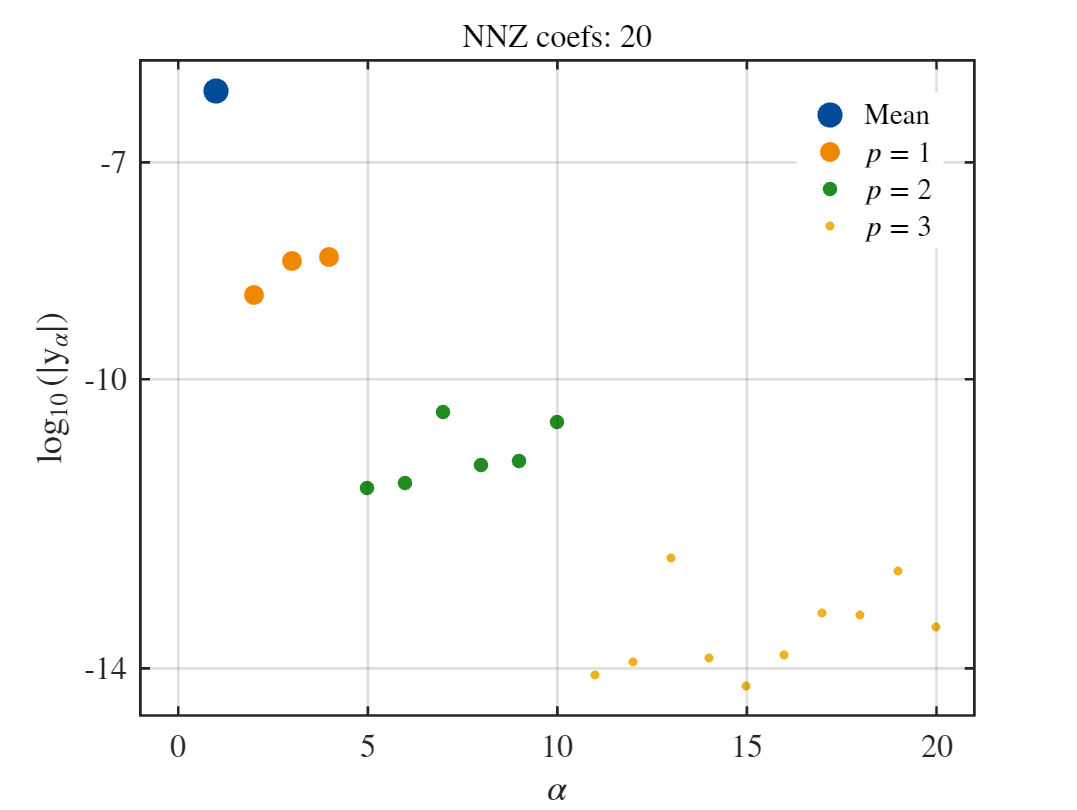

% There are 56 nonzero (nnz) coefficients
% The plot shows the magnitude of each coefficient in logscale
% The color encodes the degree of the associated polynomial
uq_display(myOLSPCE)

## 4.2 Validation of the trial PCE

Nval = 1e4;
Xval = uq_getSample(myInput, Nval);
Yval = uq_evalModel(myModel, Xval); % actual model evaluations for validation set

We evaluate the PCE on this validation set:

Yval_PCE = uq_evalModel(myOLSPCE, Xval); % OLS PCE evaluations for validation set

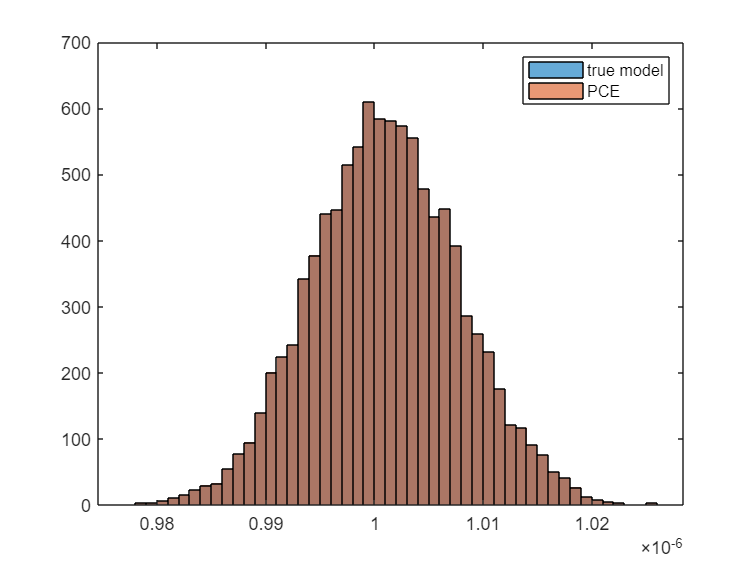

figure
histogram(Yval, 'DisplayName','true model')
hold on
histogram(Yval_PCE, 'DisplayName','PCE')
hold off
legend

The PCE surrogate is very accurate as the histograms are overlapping

**Y-Y plot**:

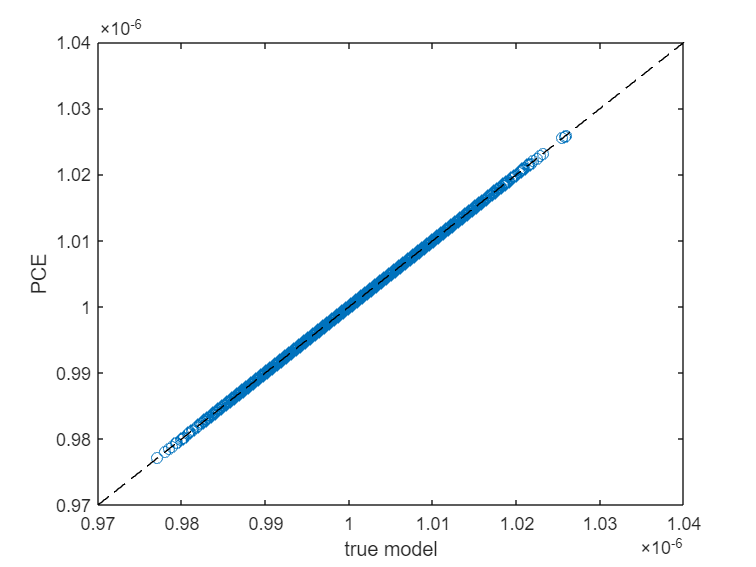

figure
plot(Yval, Yval_PCE, 'o')
hold on
plot([0.97e-6, 1.04e-6], [0.97e-6, 1.04e-6], 'k--')
xlabel('true model')
ylabel('PCE')

The points on Y-Y plot lie exactly on the dashed diagonal line and hence the PCE surrogate is accurate.

## 4.3 Error calculations

The **empirical error** is the error computed on the *experimental design*:

X = myOLSPCE.ExpDesign.X;
Y = myOLSPCE.ExpDesign.Y;
YPCE = uq_evalModel(myOLSPCE, X);

normalized_empirical_error = sum((Y - YPCE).^2) / sum((Y - mean(Y)).^2) 

normalized_empirical_error = 7.6614e-14

The **validation error** is the error computed on the *validation set*:

Yval_OLSPCE = uq_evalModel(myOLSPCE, Xval);

normalized_validation_error = mean((Yval - Yval_OLSPCE).^2) / var(Yval)

normalized_validation_error = 4.9670e-13

The normalized empirical error of *experimental design* computed by UQLab should be same as the empirical error manually calculated above:

myOLSPCE.Error.normEmpErr

ans = 7.6614e-14

But the empirical error is quite optimistic as it is calculated based on the experimental design (training set) which itself was used to train the OLS based PCE model. Therefore, validation error should be a better error estimate.

Alternatively, the Leave-One-Out *LOO error* calculated by UQLab is:

myOLSPCE.Error.LOO

ans = 3.1869e-13

LOO error is very close to the validation error calculated above and hence it can be a good estimate/replacment for the validation error.

## 4.4 Convergence study

### **4.4.1 Convergence as a function of polynomial degree:**

% Convergence study: fixed N = 1000, increasing degree from 0 to 4
clear metaopts

N = 1000;
max_degree = 4;
degree_range = 0:max_degree;

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';
metaopts.Method = 'OLS';
metaopts.Input = myInput;
metaopts.FullModel = myModel;
metaopts.ExpDesign.NSamples = N;

clear mu
clear vari

for degree = degree_range
    metaopts.Degree = degree;
    myOLSPCE(degree+1) = uq_createModel(metaopts);
    mu(degree+1) = myOLSPCE(degree+1).PCE.Moments.Mean;
    vari(degree+1) = myOLSPCE(degree+1).PCE.Moments.Var;
end

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 0 and qNorm 1.00 for output variable 1
Final LOO error estimate: 1.004009e+00
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 1 and qNorm 1.00 for output variable 1
Final LOO error estimate: 4.517022e-05
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 2 and qNorm 1.00 for output variable 1
Final LOO error estimate: 5.218789e-09
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Fin

### Visualization

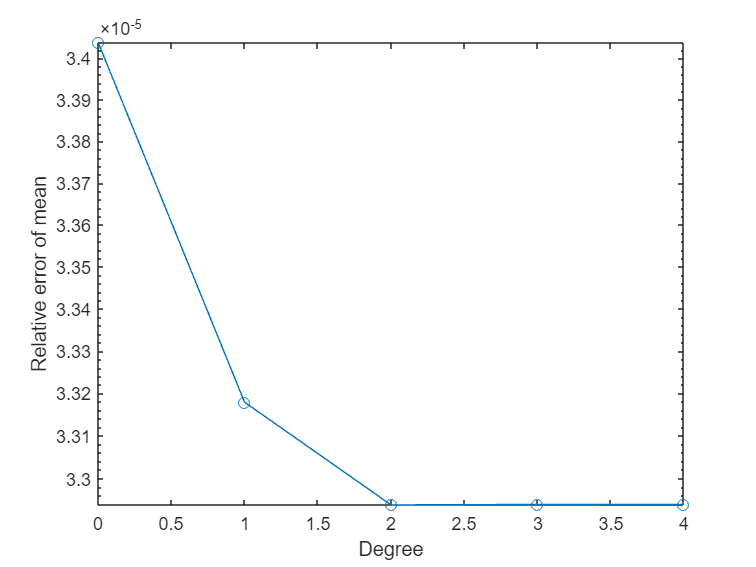

mean_val_set =  mean(Yval);
rel_mean_error_OLSPCE = abs(mu - mean_val_set)/abs(mean_val_set);

figure
plot(degree_range, rel_mean_error_OLSPCE, 'o-')
set(gca, 'yscale', 'log')
xlabel('Degree')
ylabel('Relative error of mean')

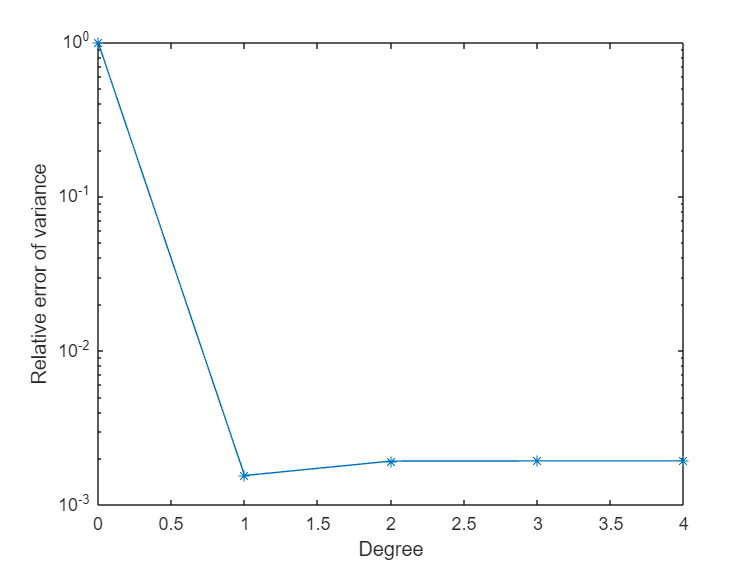

variance_val_set = var(Yval);
rel_var_error_OLSPCE = abs(vari - variance_val_set)/abs(variance_val_set);

figure
plot(degree_range, rel_var_error_OLSPCE, '*-')
set(gca, 'yscale', 'log')
xlabel('Degree')
ylabel('Relative error of variance')

### **4.4.2 Convergence as a function of number of samples in experimental design:**

% Convergence study: fixed degree = 3, increasing N from 5 to 1000
clear metaopts

p = 3;
N_sizes = [5 10 50 500 1000];

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';
metaopts.Method = 'OLS';
metaopts.Input = myInput;
metaopts.FullModel = myModel;

metaopts.Degree = p(1);

clear mu
clear vari

for N_size = 1:numel(N_sizes)
    metaopts.ExpDesign.NSamples = N_sizes(N_size);
    myOLSPCE(N_size) = uq_createModel(metaopts);
    mu(N_size) = myOLSPCE(N_size).PCE.Moments.Mean;
    vari(N_size) = myOLSPCE(N_size).PCE.Moments.Var;
end

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: 1.430640e-12
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estim

### Visualization

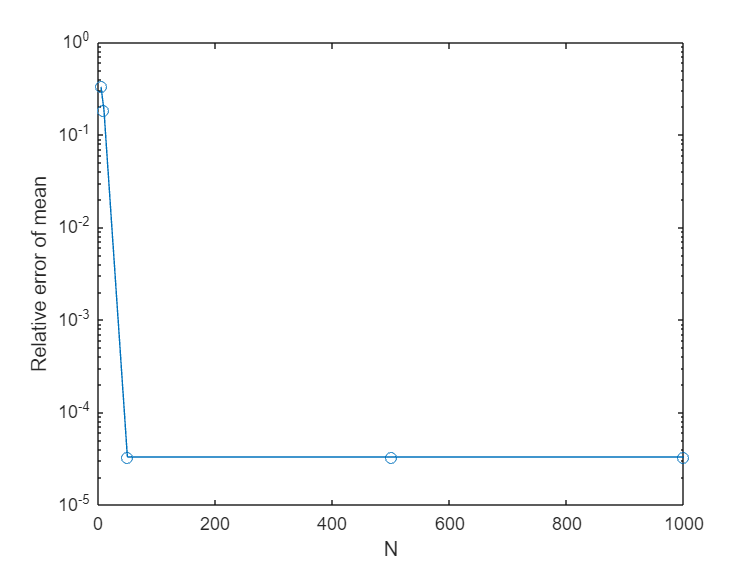

mean_val_set =  mean(Yval);
rel_mean_error_OLSPCE = abs(mu - mean_val_set)/abs(mean_val_set);

figure
plot(N_sizes, rel_mean_error_OLSPCE, 'o-')
set(gca, 'yscale', 'log')
xlabel('N')
ylabel('Relative error of mean')

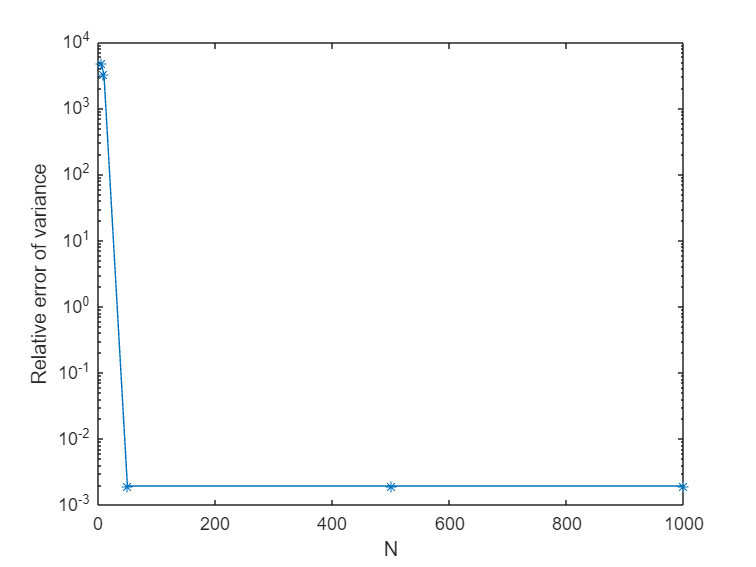

variance_val_set = var(Yval);
rel_var_error_OLSPCE = abs(vari - variance_val_set)/abs(variance_val_set);

figure
plot(N_sizes, rel_var_error_OLSPCE, '*-')
set(gca, 'yscale', 'log')
xlabel('N')
ylabel('Relative error of variance')

## 4.5 Truncation analysis on number of basis elements

clear metaopts
metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';
metaopts.Method = 'OLS';

metaopts.FullModel = myModel;
metaopts.Input = myInput;

metaopts.Degree = 4;
% >>>
metaopts.TruncOptions.qNorm = 0.8; % between 0 and 1
metaopts.TruncOptions.MaxInteraction = 3; % between 1 and 3 as we have 3 dimensions
% <<<
metaopts.ExpDesign.NSamples = 200; % N needs to be larger than P for OLS to work

myOLSPCE = uq_createModel(metaopts);

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 4 and qNorm 0.80 for output variable 1
Final LOO error estimate: 4.108580e-13
---                 Calculation finished!                               ---


Number of basis elements (number of coefficients in the PCE):

numBasisElements = numel(myOLSPCE.PCE.Coefficients)

numBasisElements = 23

## 4.6 Convergence study of full vs sparse PCE (LARS)

The degree and the hyperbolic truncation for LARS-PCE are determined adaptively (based on the LOO error), degree of OLS-PCE is fixed as 3. The samples drawn for both LARS-PCE and OLS-PCE are same for comparing the results.

N_sizes = [5 10 50 500 1000]; %Sizes of experimental design

X = cell(size(N_sizes));
Y = cell(size(N_sizes));

for N_size = 1:numel(N_sizes)
    X{N_size} = uq_getSample(myInput, N_sizes(N_size), 'MC'); % Monte Carlo based sampling
    Y{N_size} = uq_evalModel(myModel, X{N_size});
end

mean_val_set =  mean(Yval); %Mean of validation set defined earlier
variance_val_set = var(Yval); %Variance of validation set defined earlier

% OLS-PCE: fixed degree = 3, increasing N from 5 to 1000
clear metaopts

p = 3;

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';
metaopts.Method = 'OLS';
metaopts.Input = myInput;
metaopts.FullModel = myModel;
metaopts.Degree = p(1);

clear mu_OLS
clear vari_OLS

for N_size = 1:numel(N_sizes)
    metaopts.ExpDesign.X = X{N_size};  %Fixing the experimental design to the drawn samples
    metaopts.ExpDesign.Y = Y{N_size};
    
    myOLSPCE(N_size) = uq_createModel(metaopts); %Create the OLS-PCE
    mu_OLS(N_size) = myOLSPCE(N_size).PCE.Moments.Mean;
    vari_OLS(N_size) = myOLSPCE(N_size).PCE.Moments.Var;
end

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: 7.058546e-13
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estim


% LARS-PCE: adaptive degree and truncation, increasing N from 5 to 1000
clear metaopts

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';
metaopts.Method = 'LARS'; % LARS solver for sparse regression
metaopts.Input = myInput;
metaopts.FullModel = myModel;

% Degree- and q-norm adaptivity:
metaopts.Degree = 1:10;
metaopts.TruncOptions.qNorm = 0.5:0.1:1.0;

clear mu_LARS
clear vari_LARS

for N_size = 1:numel(N_sizes)
    metaopts.ExpDesign.X = X{N_size};  %Fixing the experimental design to the drawn samples
    metaopts.ExpDesign.Y = Y{N_size};
    
    myLARSPCE(N_size) = uq_createModel(metaopts); %Create the LARS-PCE
    mu_LARS(N_size) = myLARSPCE(N_size).PCE.Moments.Mean;
    vari_LARS(N_size) = myLARSPCE(N_size).PCE.Moments.Var;
end

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 1 and qNorm 0.50 for output variable 1
Final LOO error estimate: 5.002314e-01
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 1 and qNorm 0.50 for output variable 1
Final LOO error estimate: 1.325693e-04
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 4 and qNorm 1.00 for output variable 1
Final LOO error estimate: 1.274461e-14
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 4 and qNorm 1.00 for output variable


rel_mean_error_OLSPCE = abs(mu_OLS - mean_val_set)/abs(mean_val_set);
rel_var_error_OLSPCE = abs(vari_OLS - variance_val_set)/abs(variance_val_set);

rel_mean_error_LARSPCE = abs(mu_LARS - mean_val_set)/abs(mean_val_set);
rel_var_error_LARSPCE = abs(vari_LARS - variance_val_set)/abs(variance_val_set);

### Visualization

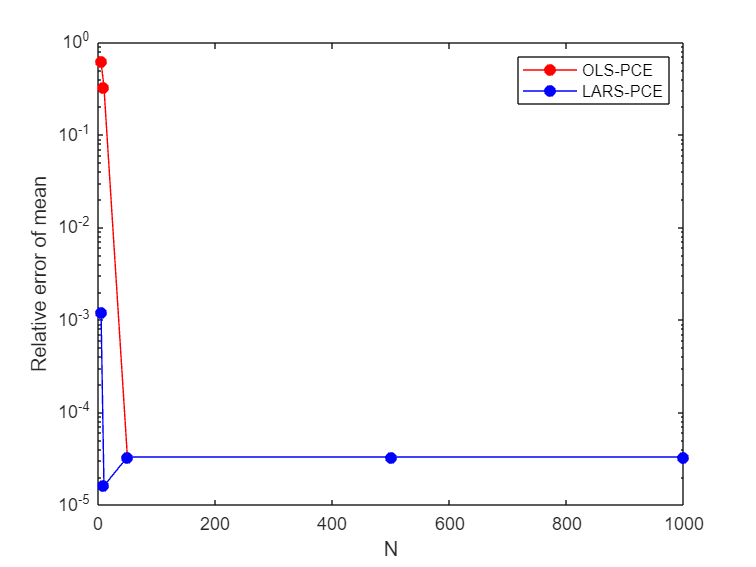

figure
plot(N_sizes, rel_mean_error_OLSPCE, 'o-', 'Color', 'red', 'MarkerFaceColor', 'red')
hold on
plot(N_sizes, rel_mean_error_LARSPCE, 'o-', 'Color', 'blue', 'MarkerFaceColor', 'blue')
hold off
legend('OLS-PCE', 'LARS-PCE')
set(gca, 'yscale', 'log')
xlabel('N')
ylabel('Relative error of mean')

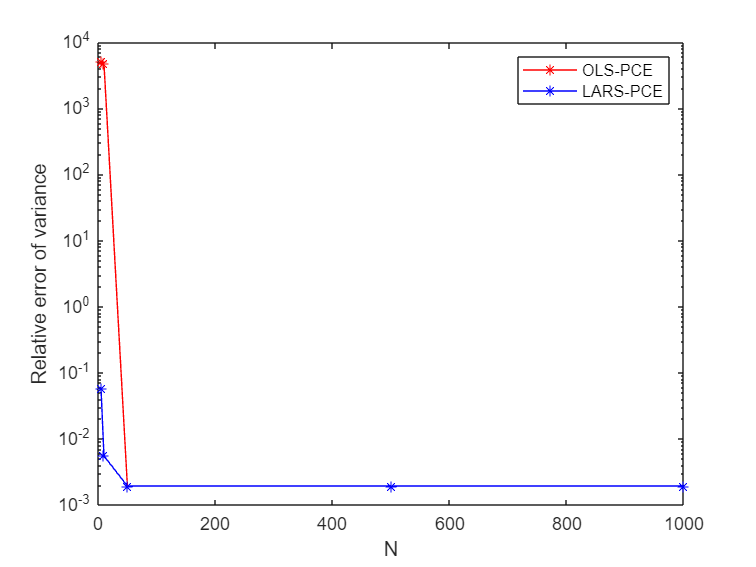

figure
plot(N_sizes, rel_var_error_OLSPCE, '*-', 'Color', 'red', 'MarkerFaceColor', 'red')
hold on
plot(N_sizes, rel_var_error_LARSPCE, '*-', 'Color', 'blue', 'MarkerFaceColor', 'blue')
hold off
legend('OLS-PCE', 'LARS-PCE')
set(gca, 'yscale', 'log')
xlabel('N')
ylabel('Relative error of variance')

## 4.7 Convergence study of full vs sparse PCE (OMP)

The degree and the hyperbolic truncation for OMP-PCE are determined adaptively (based on the LOO error), degree of OLS-PCE is fixed as 3. The samples drawn for both OMP-PCE and OLS-PCE are same for comparing the results.

N_sizes = [5 10 50 500 1000]; %Sizes of experimental design

X = cell(size(N_sizes));
Y = cell(size(N_sizes));

for N_size = 1:numel(N_sizes)
    X{N_size} = uq_getSample(myInput, N_sizes(N_size), 'MC'); % Monte Carlo based sampling
    Y{N_size} = uq_evalModel(myModel, X{N_size});
end

mean_val_set =  mean(Yval); %Mean of validation set defined earlier
variance_val_set = var(Yval); %Variance of validation set defined earlier

% OLS-PCE: fixed degree = 3, increasing N from 5 to 1000
clear metaopts

p = 3;

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';
metaopts.Method = 'OLS';
metaopts.Input = myInput;
metaopts.FullModel = myModel;
metaopts.Degree = p(1);

clear mu_OLS
clear vari_OLS

for N_size = 1:numel(N_sizes)
    metaopts.ExpDesign.X = X{N_size};  %Fixing the experimental design to the drawn samples
    metaopts.ExpDesign.Y = Y{N_size};
    
    myOLSPCE(N_size) = uq_createModel(metaopts); %Create the OLS-PCE
    mu_OLS(N_size) = myOLSPCE(N_size).PCE.Moments.Mean;
    vari_OLS(N_size) = myOLSPCE(N_size).PCE.Moments.Var;
end

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: 2.809077e-12
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estim


% OMP-PCE: adaptive degree and truncation, increasing N from 5 to 1000
clear metaopts

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';
metaopts.Method = 'OMP'; % OMP solver for sparse regression
metaopts.Input = myInput;
metaopts.FullModel = myModel;

% Degree- and q-norm adaptivity:
metaopts.Degree = 1:10;
metaopts.TruncOptions.qNorm = 0.5:0.1:1.0;

clear mu_OMP
clear vari_OMP

for N_size = 1:numel(N_sizes)
    metaopts.ExpDesign.X = X{N_size};  %Fixing the experimental design to the drawn samples
    metaopts.ExpDesign.Y = Y{N_size};
    
    myOMPPCE(N_size) = uq_createModel(metaopts); %Create the OMP-PCE
    mu_OMP(N_size) = myOMPPCE(N_size).PCE.Moments.Mean;
    vari_OMP(N_size) = myOMPPCE(N_size).PCE.Moments.Var;
end

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 1 and qNorm 0.50 for output variable 1
Final LOO error estimate: 6.795006e-04
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 5 and qNorm 0.60 for output variable 1
Final LOO error estimate: 5.799507e-05
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 4 and qNorm 1.00 for output variable 1
Final LOO error estimate: 6.064501e-15
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 5 and qNorm 0.90 for output variable


rel_mean_error_OLSPCE = abs(mu_OLS - mean_val_set)/abs(mean_val_set);
rel_var_error_OLSPCE = abs(vari_OLS - variance_val_set)/abs(variance_val_set);

rel_mean_error_OMPPCE = abs(mu_OMP - mean_val_set)/abs(mean_val_set);
rel_var_error_OMPPCE = abs(vari_OMP - variance_val_set)/abs(variance_val_set);

### Visualization

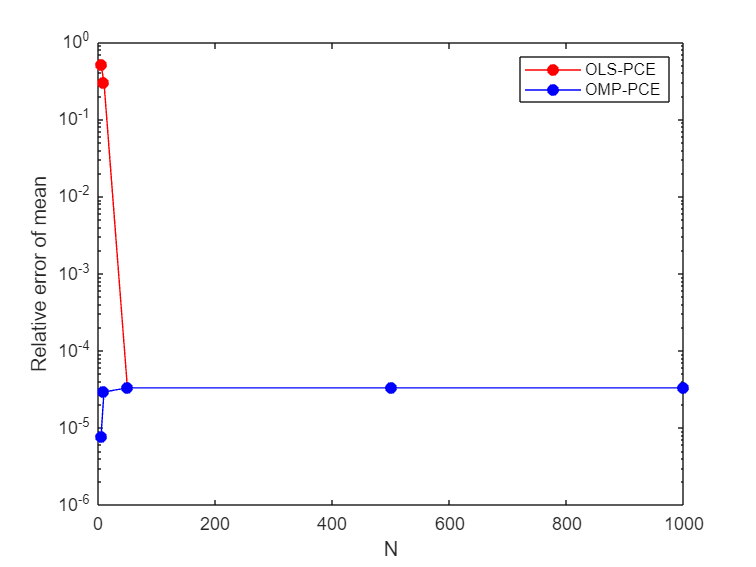

figure
plot(N_sizes, rel_mean_error_OLSPCE, 'o-', 'Color', 'red', 'MarkerFaceColor', 'red')
hold on
plot(N_sizes, rel_mean_error_OMPPCE, 'o-', 'Color', 'blue', 'MarkerFaceColor', 'blue')
hold off
legend('OLS-PCE', 'OMP-PCE')
set(gca, 'yscale', 'log')
xlabel('N')
ylabel('Relative error of mean')

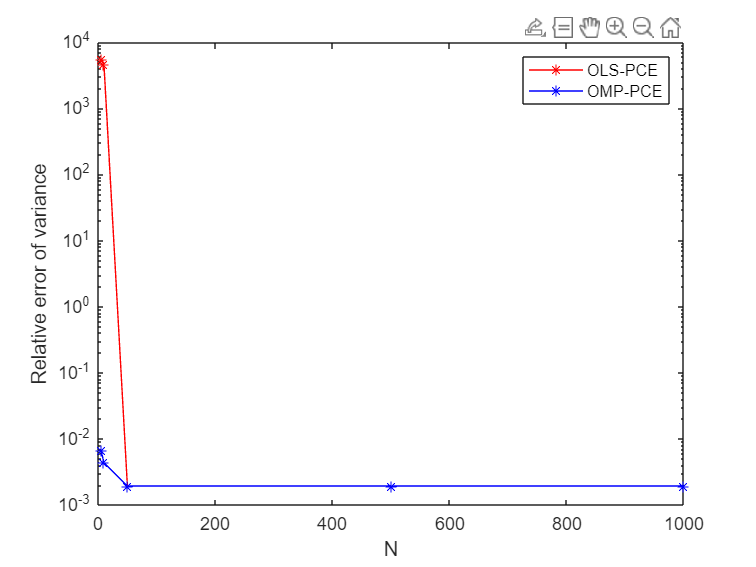

figure
plot(N_sizes, rel_var_error_OLSPCE, '*-', 'Color', 'red', 'MarkerFaceColor', 'red')
hold on
plot(N_sizes, rel_var_error_OMPPCE, '*-', 'Color', 'blue', 'MarkerFaceColor', 'blue')
hold off
legend('OLS-PCE', 'OMP-PCE')
set(gca, 'yscale', 'log')
xlabel('N')
ylabel('Relative error of variance')